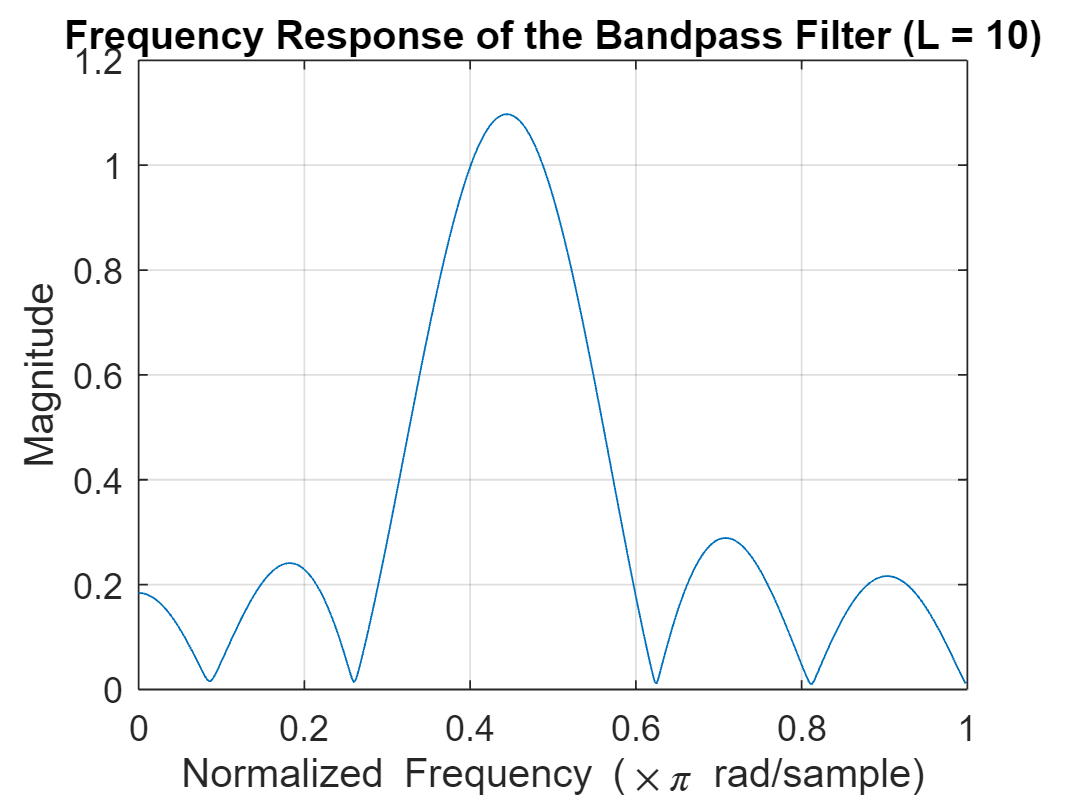

% Define the filter length
L = 10;
wc = 0.44 * pi;

% Generate the bandpass filter coefficients using the cosine method
h = (2 / L) * cos(wc * (0:(L-1)));

% Frequency response
[H, W] = freqz(h, 1, 512);

% Plot the frequency response
figure;
plot(W/pi, abs(H));
title('Frequency Response of the Bandpass Filter (L = 10)');
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude');
grid on;


% Measure the gain at specific frequencies
freqs = [0.3, 0.44, 0.7] * pi;
gains = abs(freqz(h, 1, freqs));
disp('Gains at specified frequencies:');

Gains at specified frequencies:


disp(['Frequency 0.3\pi: ', num2str(gains(1))]);

Frequency 0.3\pi: 0.28362


disp(['Frequency 0.44\pi: ', num2str(gains(2))]);

Frequency 0.44\pi: 1.0961


disp(['Frequency 0.7\pi: ', num2str(gains(3))]);

Frequency 0.7\pi: 0.28614


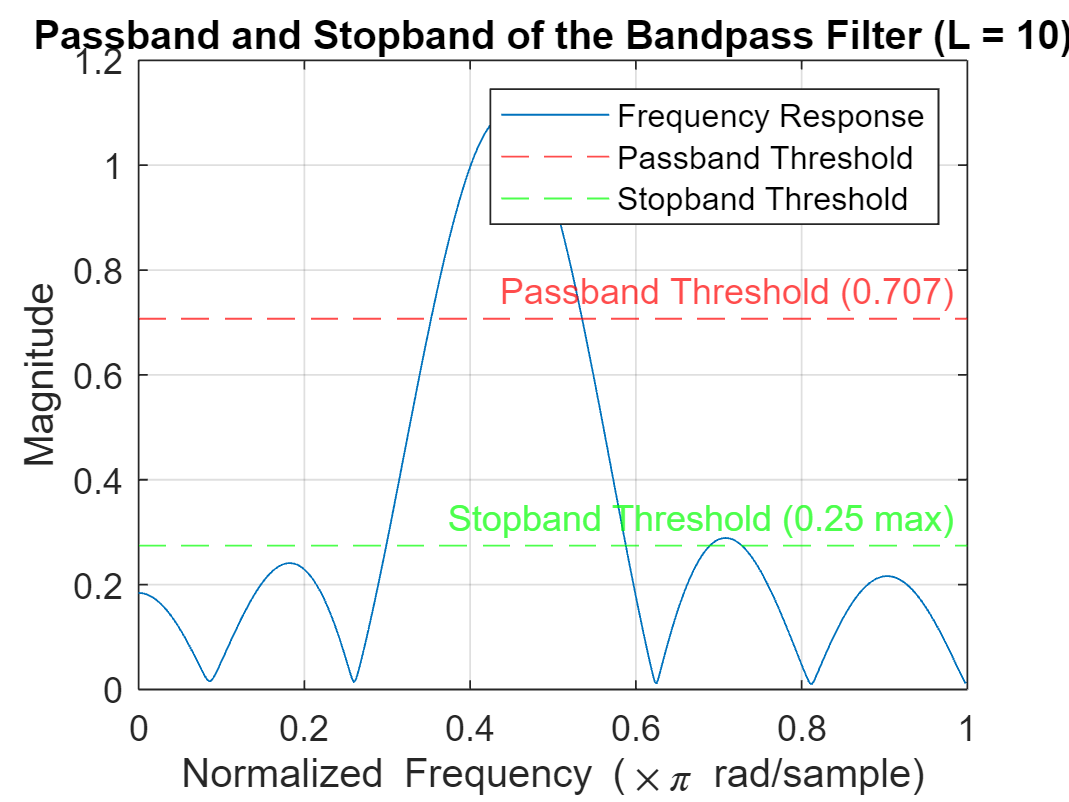


%B ----------------------------
% Passband and Stopband determination
passband_threshold = 1/sqrt(2);
stopband_threshold = 0.25 * max(abs(H));

% Plot with thresholds
figure;
plot(W/pi, abs(H));
hold on;
yline(passband_threshold, 'r--', 'Passband Threshold (0.707)');
yline(stopband_threshold, 'g--', 'Stopband Threshold (0.25 max)');
title('Passband and Stopband of the Bandpass Filter (L = 10)');
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude');
legend('Frequency Response', 'Passband Threshold', 'Stopband Threshold');
grid on;

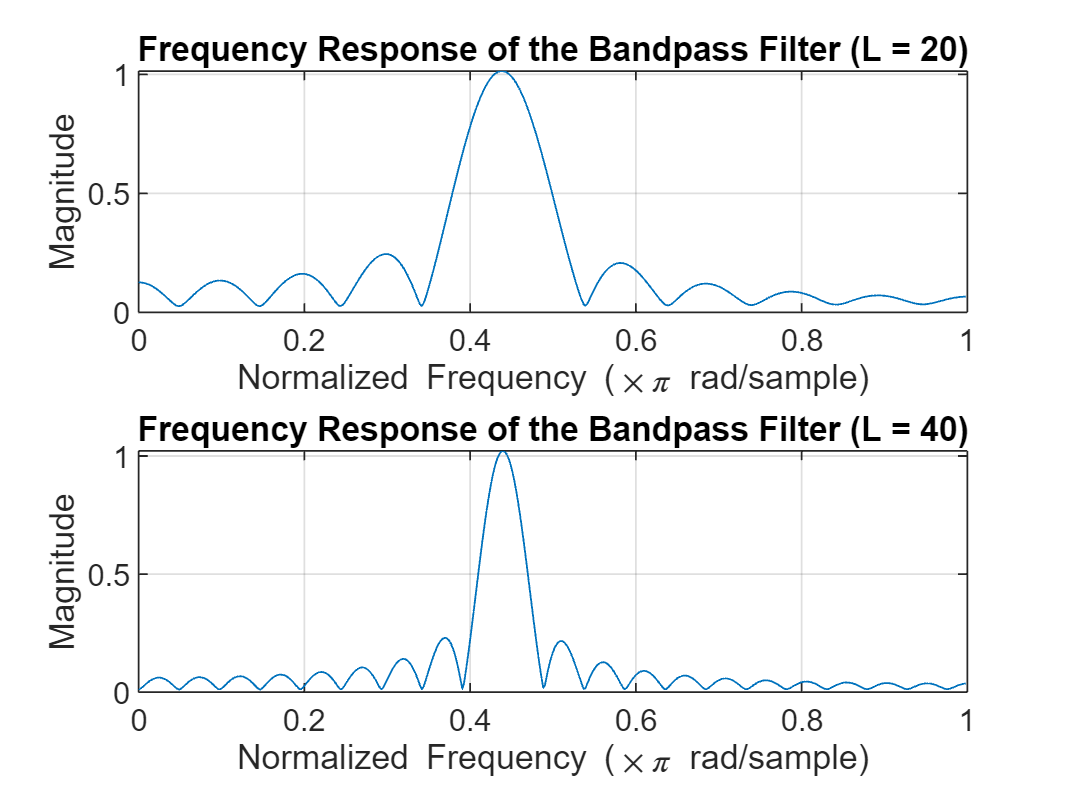


%C --------------------
% The filter with L = 10 is selective in allowing the frequency component at 0.44π to pass,
% while significantly reducing the components at 0.3π and 0.7π.

%D
% Define longer filter lengths
L1 = 20;
L2 = 40;

% Generate filters using the cosine method
h1 = (2 / L1) * cos(wc * (0:(L1-1)));
h2 = (2 / L2) * cos(wc * (0:(L2-1)));

% Frequency responses
[H1, W1] = freqz(h1, 1, 512);
[H2, W2] = freqz(h2, 1, 512);

% Plot the frequency responses
figure;
subplot(2,1,1);
plot(W1/pi, abs(H1));
title('Frequency Response of the Bandpass Filter (L = 20)');
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude');
grid on;

subplot(2,1,2);
plot(W2/pi, abs(H2));
title('Frequency Response of the Bandpass Filter (L = 40)');
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude');
grid on;

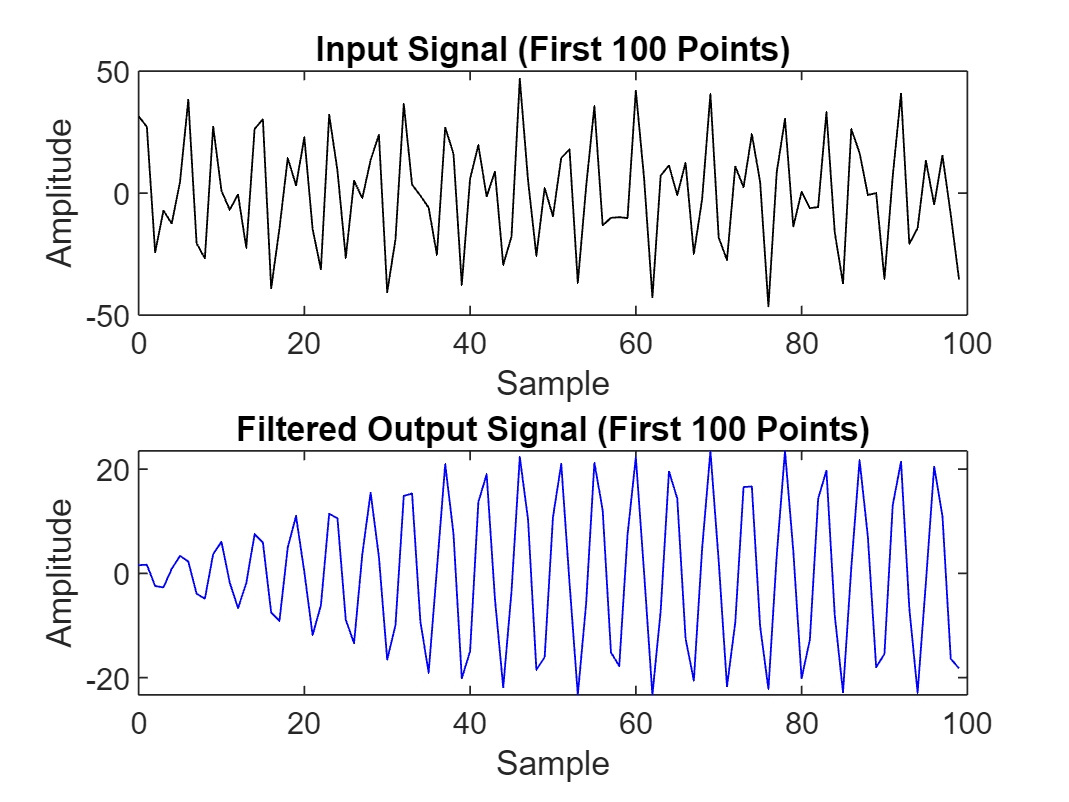



%e ------------------
% Generate the input signal
n = 0:149;
x = 5*cos(0.3*pi*n) + 22*cos(0.44*pi*n - pi/3) + 22*cos(0.7*pi*n - pi/4);

% Filter the signal using L = 40 filter (assuming this is the best length)
y_filtered = firfilt(h2, x);

% Plot input and output signals (first 100 points)
figure;
subplot(2,1,1);
plot(n(1:100), x(1:100), 'k');
title('Input Signal (First 100 Points)');
xlabel('Sample');
ylabel('Amplitude');

subplot(2,1,2);
plot(n(1:100), y_filtered(1:100), 'b');
title('Filtered Output Signal (First 100 Points)');
xlabel('Sample');
ylabel('Amplitude');

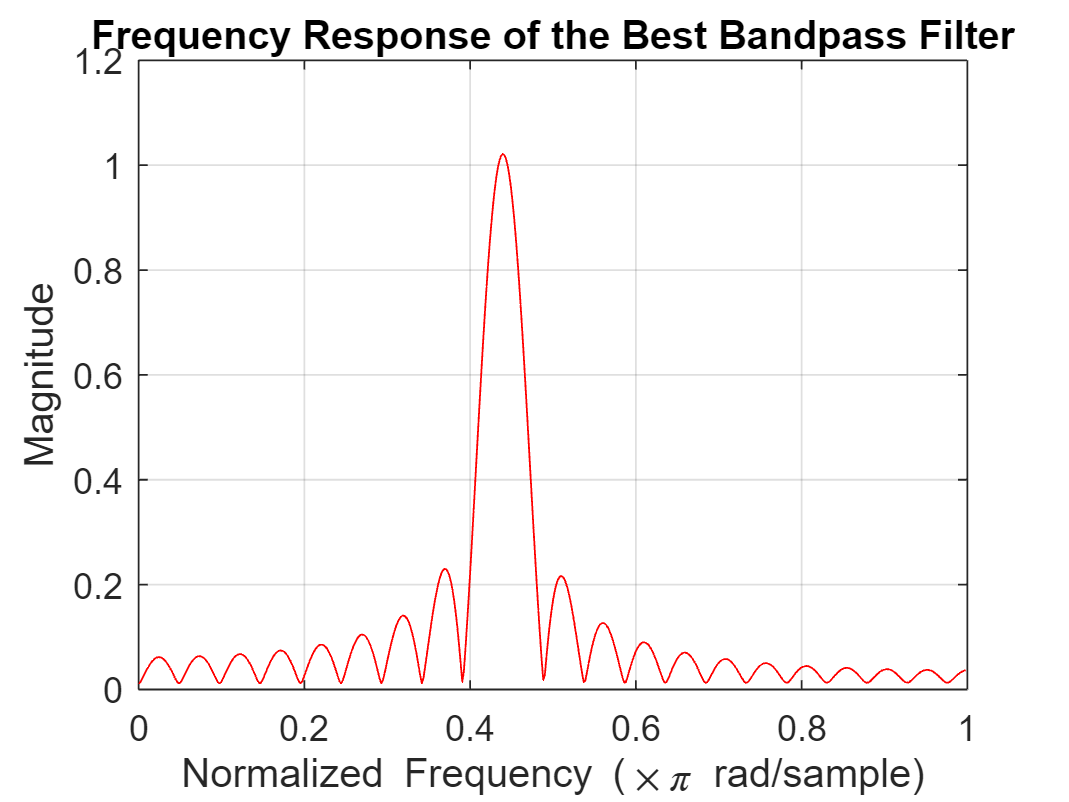


%f -----------------------
% Plot frequency response of the filter from part (d)
figure;
plot(W2/pi, abs(H2), 'r');
title('Frequency Response of the Best Bandpass Filter');
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude');
grid on;


% Explanation
% The magnitude plot shows how much each frequency component is reduced or allowed to pass.
% Use the values from this plot to explain the relative size of each sinusoidal component in the output signal.

